clc; 
clear; 
close all; 

filepath = '/Users/abbyskerker/Documents/Spring24/EC520/Project/flash_data_JBF_Detail_transfer/flash_data_JBF_Detail_transfer/';
filename_flash = 'carpet_00_flash.tif';
filename_noflash = 'carpet_01_noflash.tif';
fn = strcat(filepath,filename_flash);
flash_img = (imread(fn)); 
fn = strcat(filepath,filename_noflash);
noflash_img = (imread(fn)); 

f_width = 10;

%Bilateral Filter on Flash Image
F1 = flash_img(:,:,1);
F2 = flash_img(:,:,2);
F3 = flash_img(:,:,3);
F = flash_img;
F_base = zeros(size(flash_img));
sigma_d = 48; % set at 24-48 pixels
sigma_r = 20; % 5-10% of range of color vals
F_base(:,:,1) = bilat_filt_1d(double(F1),f_width,sigma_d,sigma_r);
F_base(:,:,2) = bilat_filt_1d(double(F2),f_width,sigma_d,sigma_r);
F_base(:,:,3) = bilat_filt_1d(double(F3),f_width,sigma_d,sigma_r);


%Detail Transfer on Flash Image
epsilon = 0.02; %says in paper 0.02, assuming of 1
F_rescale = rescale(F); 
F_base_rescale = rescale(F_base);
F_detail = (F_rescale+epsilon)./(F_base_rescale + epsilon); 


%Bilateral Filter on No Flash Image
A1 = noflash_img(:,:,1);
A2 = noflash_img(:,:,2);
A3 = noflash_img(:,:,3);
A = noflash_img;
sigma_d = 48; % set at 24-48 pixels
sigma_r = 20; % 5-10% of range of color vals
A_base = zeros(size(noflash_img));
A_base(:,:,1) = bilat_filt_1d(double(A1),f_width,sigma_d,sigma_r);
A_base(:,:,2) = bilat_filt_1d(double(A2),f_width,sigma_d,sigma_r);
A_base(:,:,3) = bilat_filt_1d(double(A3),f_width,sigma_d,sigma_r);


%Joint Bilateral Filter on No Flash Image
A1 = noflash_img(:,:,1);
A2 = noflash_img(:,:,2);
A3 = noflash_img(:,:,3);
sigma_d = 48; % set at 24-48 pixels
sigma_r = 0.001*256; % 0.1% of 256
A_NR = zeros(size(noflash_img));
A_NR(:,:,1) = joint_bilat_filt_1d(double(F1),double(A1),f_width,sigma_d,sigma_r);
A_NR(:,:,2) = joint_bilat_filt_1d(double(F2),double(A2),f_width,sigma_d,sigma_r);
A_NR(:,:,3) = joint_bilat_filt_1d(double(F3),double(A3),f_width,sigma_d,sigma_r);

%Final Image
M = 0; %Mask
%A_NR_rescale = rescale(A_NR); 
A_final = (1-M)*A_NR.*F_detail + M*A_base;


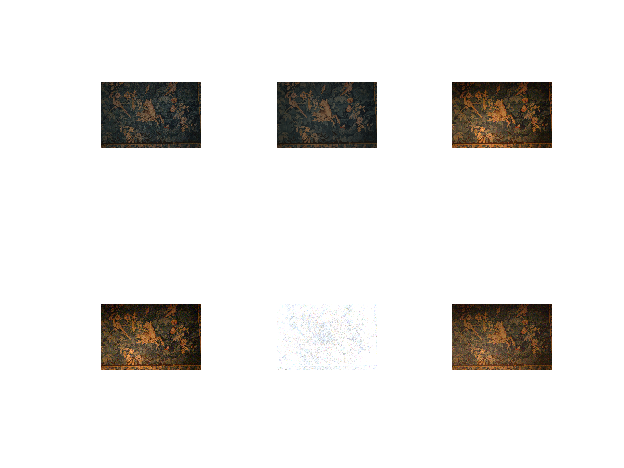


figure; 
subplot(2,3,1)
imshow(flash_img);
subplot(2,3,4);
imshow(noflash_img);
subplot(2,3,2);
imshow(uint8(F_base));
subplot(2,3,5)
imshow(F_detail);
subplot(2,3,3)
imshow(uint8(A_NR));
subplot(2,3,6)
imshow(uint8(A_final));

Notes from Petshnigg Paper: 

- They apply the bilateral filter to each RGB color channel seperately

- Set same standard deviation parameters for all three channels

- For 6mega pixel images, sigma_d covers a neighborhood of 24-48 pixels

- Set sigma_r to 5-10% of total range of pixel values

function h = bilat_filt(f, width, sigma_d, sigma_r)
    
    %Note: variable notation used is from the Tomasi Paper

    %convert from rgb to lab
    f = rgb2lab(f);

    % Compute Closeness Function (Gaussian)
    [X,Y] = meshgrid(-width:width,-width:width);
    c = exp(-1/2*(X.^2+Y.^2)/sigma_d^2); %g_d in the Petshnigg Paper
    
    %Setup Variables
    dim = size(f);
    h = zeros(dim);
    height = dim(1); 
    width = dim(2);

    %Loop through each location in image
    for i = 1:height
        for j = 1:width
            % Get local region
            iMin = max(i-width,1);
            iMax = min(i+width,height);
            jMin = max(j-width,1);
            jMax = min(j+width,width);
            I = f(iMin:iMax, jMin:jMax,:);
            
            % Compute similarity function (Gaussian)
            dL = I(:,:,1)-f(i,j,1);
            da = I(:,:,2)-f(i,j,2);
            db = I(:,:,3)-f(i,j,3);
            s = exp(-1/2*(dL.^2+da.^2+db.^2)/sigma_r^2); %g_r in the Petshnigg Paper
            
            % Compute Normalization Constant
            k = s.*c((iMin:iMax)-i+width+1, (jMin:jMax)-j+width+1);
            k_inv = 1/sum(k(:));

            % Compute Output Image
            h(i,j,1) = sum(sum(k.*I(:,:,1)))*k_inv;
            h(i,j,2) = sum(sum(k.*I(:,:,2)))*k_inv;
            h(i,j,3) = sum(sum(k.*I(:,:,3)))*k_inv;            
        end
    end
    
    %Convert back to RGB space
    h = lab2rgb(h);
end

function h = bilat_filt_1d(f, width, sigma_d, sigma_r)
    
    %Note: variable notation used is from the Tomasi Paper

    % Compute Closeness Function (Gaussian)
    [X,Y] = meshgrid(-width:width,-width:width);
    c = exp(-1/2*(X.^2+Y.^2)/sigma_d^2); %g_d in the Petshnigg Paper
    
    %Setup Variables
    dim = size(f);
    h = zeros(dim);
    im_height = dim(1); 
    im_width = dim(2);

    %Loop through each location in image
    for i = 1:im_height
        for j = 1:im_width
            % Get local region
            iMin = max(i-width,1);
            iMax = min(i+width,im_height);
            jMin = max(j-width,1);
            jMax = min(j+width,im_width);
            I = f(iMin:iMax, jMin:jMax);
            
            % Compute similarity function (Gaussian)
            d1 = I(:,:)-f(i,j);
            s = exp(-1/2*(d1.^2)/sigma_r^2); %g_r in the Petshnigg Paper
            
            % Compute Normalization Constant
            k = s.*c((iMin:iMax)-i+width+1, (jMin:jMax)-j+width+1);
            k_inv = 1/sum(k(:));

            % Compute Output Image
            h(i,j) = sum(sum(k.*I(:,:)))*k_inv;           
        end
    end
    
end

function h = joint_bilat_filt_1d(flash_img,noflash_img, width, sigma_d, sigma_r)
    
    %Note: variable notation used is from the Tomasi Paper

    % Compute Closeness Function (Gaussian)
    [X,Y] = meshgrid(-width:width,-width:width);
    c = exp(-1/2*(X.^2+Y.^2)/sigma_d^2); %g_d in the Petshnigg Paper
    
    %Setup Variables
    dim = size(flash_img);
    h = zeros(dim);
    im_height = dim(1); 
    im_width = dim(2);

    %Loop through each location in image
    for i = 1:im_height
        for j = 1:im_width
            % Get local region
            iMin = max(i-width,1);
            iMax = min(i+width,im_height);
            jMin = max(j-width,1);
            jMax = min(j+width,im_width);
            I_flash = flash_img(iMin:iMax, jMin:jMax);
            I_noflash = noflash_img(iMin:iMax, jMin:jMax);
            
            % Compute similarity function (Gaussian)
            d1 = I_flash(:,:)-flash_img(i,j);
            s_flash = exp(-1/2*(d1.^2)/sigma_r^2); %g_r in the Petshnigg Paper
            d1 = I_noflash(:,:)-flash_img(i,j);
            s_noflash = exp(-1/2*(d1.^2)/sigma_r^2); %g_r in the Petshnigg Paper

            % Compute Normalization Constant
            k = s_noflash.*c((iMin:iMax)-i+width+1, (jMin:jMax)-j+width+1);
            k_inv = 1/sum(k(:));
            k_flash = s_flash.*c((iMin:iMax)-i+width+1, (jMin:jMax)-j+width+1);
            k_inv = 1/sum(k_flash(:));
            % Compute Output Image
            h(i,j) = sum(sum(k_flash.*I_noflash(:,:)))*k_inv;           
        end
    end

end

